clear

Part a

dt = 0.1;   % t step
f = 1;      % Frequency

v = @(t) 0.5*exp(1i*(2*pi*f*t));
w = @(t) 0.5*exp(1i*(2*pi*f*(t-dt)));
c = @(t) v(linspace(t-dt,t,20));

Part b

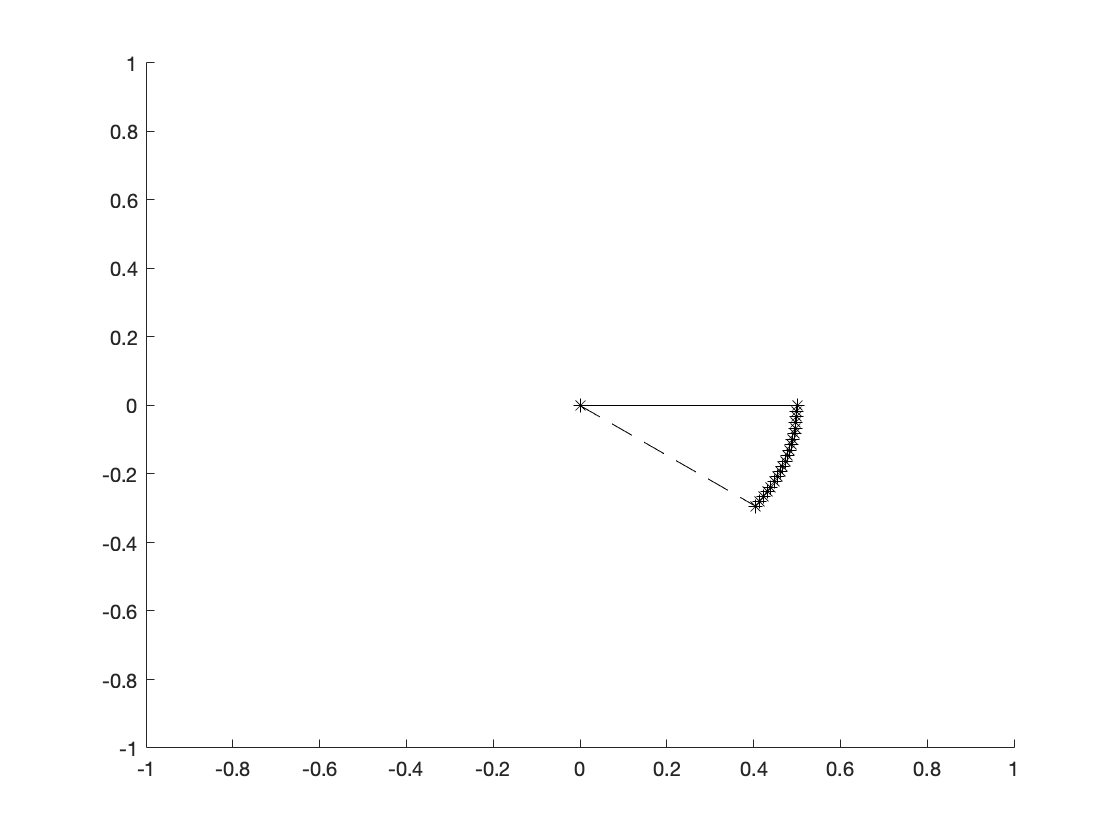

hold on
plot([0 real(v(0))], [0, imag(v(0))], 'k')
plot([0 real(w(0))], [0, imag(w(0))], 'k--')
plot([0 real(c(0))], [0, imag(c(0))], 'k*')
axis([-1 1 -1 1])
hold off

Part c

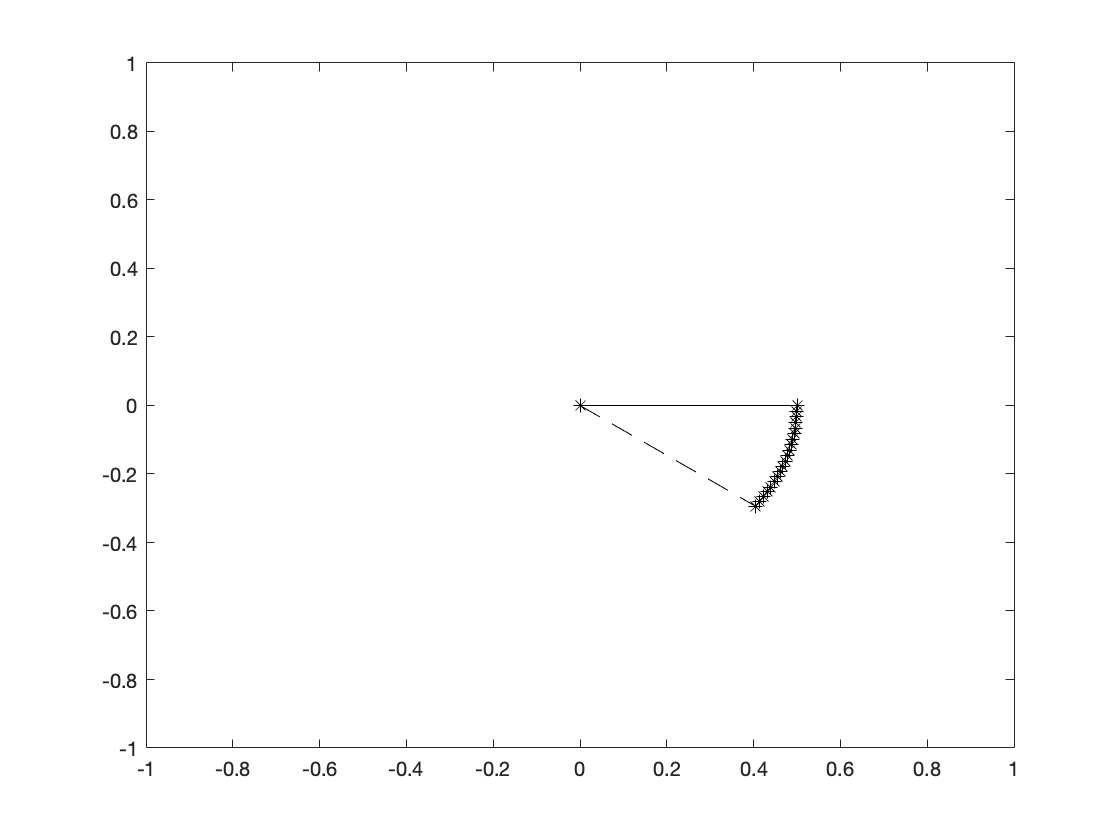

figure()
for t = 0:dt:2
    plot([0 real(v(t))], [0, imag(v(t))], 'k')
    hold on
    axis([-1 1 -1 1])
    plot([0 real(w(t))], [0, imag(w(t))], 'k--')
    plot([0 real(c(t))], [0, imag(c(t))], 'k*')
    pause(0.1)
    
    hold off
end

Part d

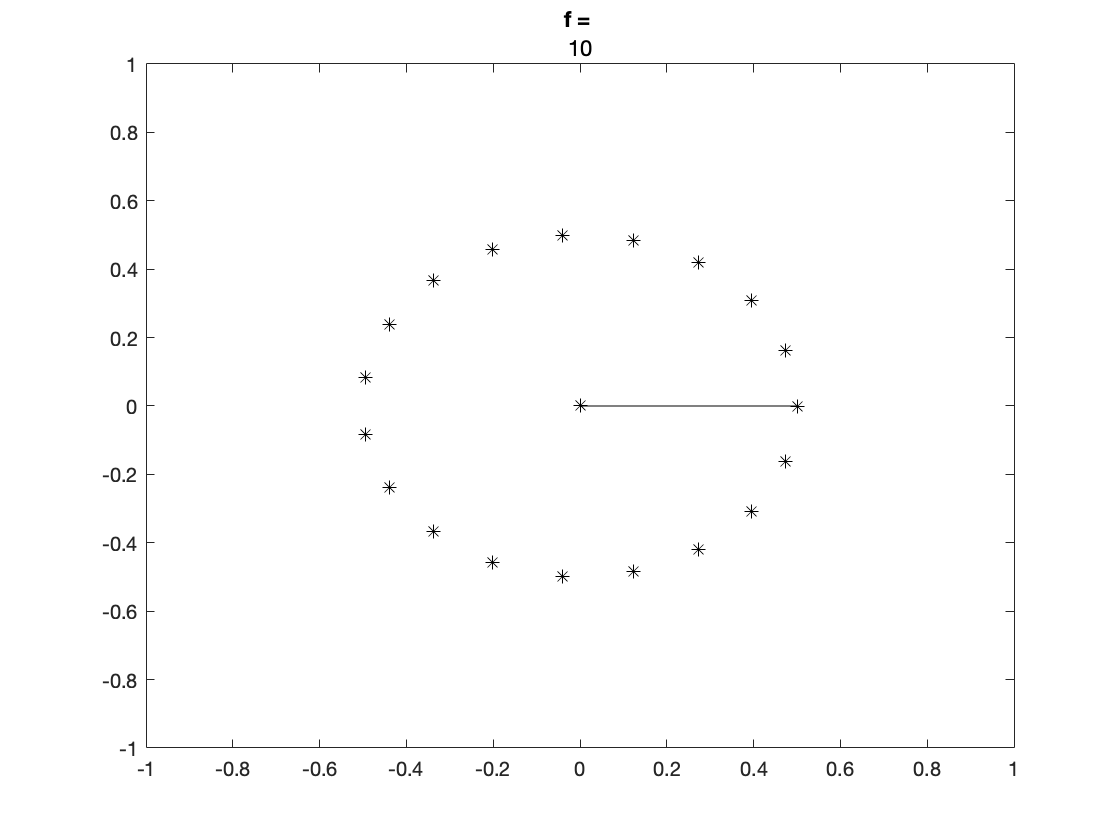

figure()
for f = [1 1.5 2 2.5 5 7.5 8 8.5 9 10]
    v = @(t) 0.5*exp(1i*(2*pi*f*t));
    w = @(t) 0.5*exp(1i*(2*pi*f*(t-dt)));
    c = @(t) v(linspace(t-dt,t,20));
    for t = 0:dt:2
        plot([0 real(v(t))], [0, imag(v(t))], 'k')
        hold on
        axis([-1 1 -1 1])
        title("f = ", f)
        plot([0 real(w(t))], [0, imag(w(t))], 'k--')
        plot([0 real(c(t))], [0, imag(c(t))], 'k*')
        pause(0.1)
        hold off
    end
end

The shape appears to be rotating left until f=5. At f = 5, the shape appears to be flipping back and forth. After f=5, the shape appears to be rotating right.

Part e

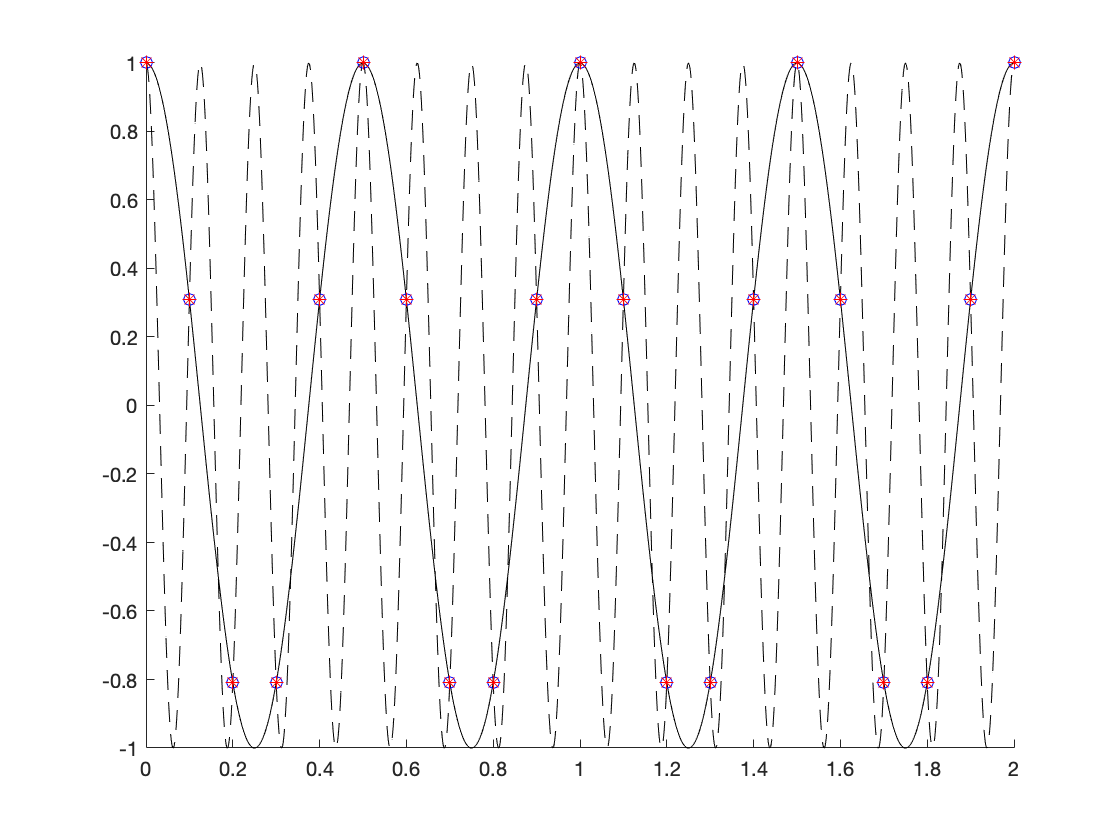

t1 = 0:dt/100:2; % Time 1
t2 = 0:dt:2;     % Time 2
dt = 0.1;        % t step
f = 8;           % Frequency

v1 = @(t) cos(2*pi*f*t);
v2 = @(t) cos(2*pi*(f-1/dt)*t);

figure()
hold on
plot(t1, v1(t1), 'k--')
plot(t1, v2(t1), 'k')
plot(t2, v1(t2), 'bo')
plot(t2, v2(t2), 'r*')
axis([0 2 -1 1])
hold off